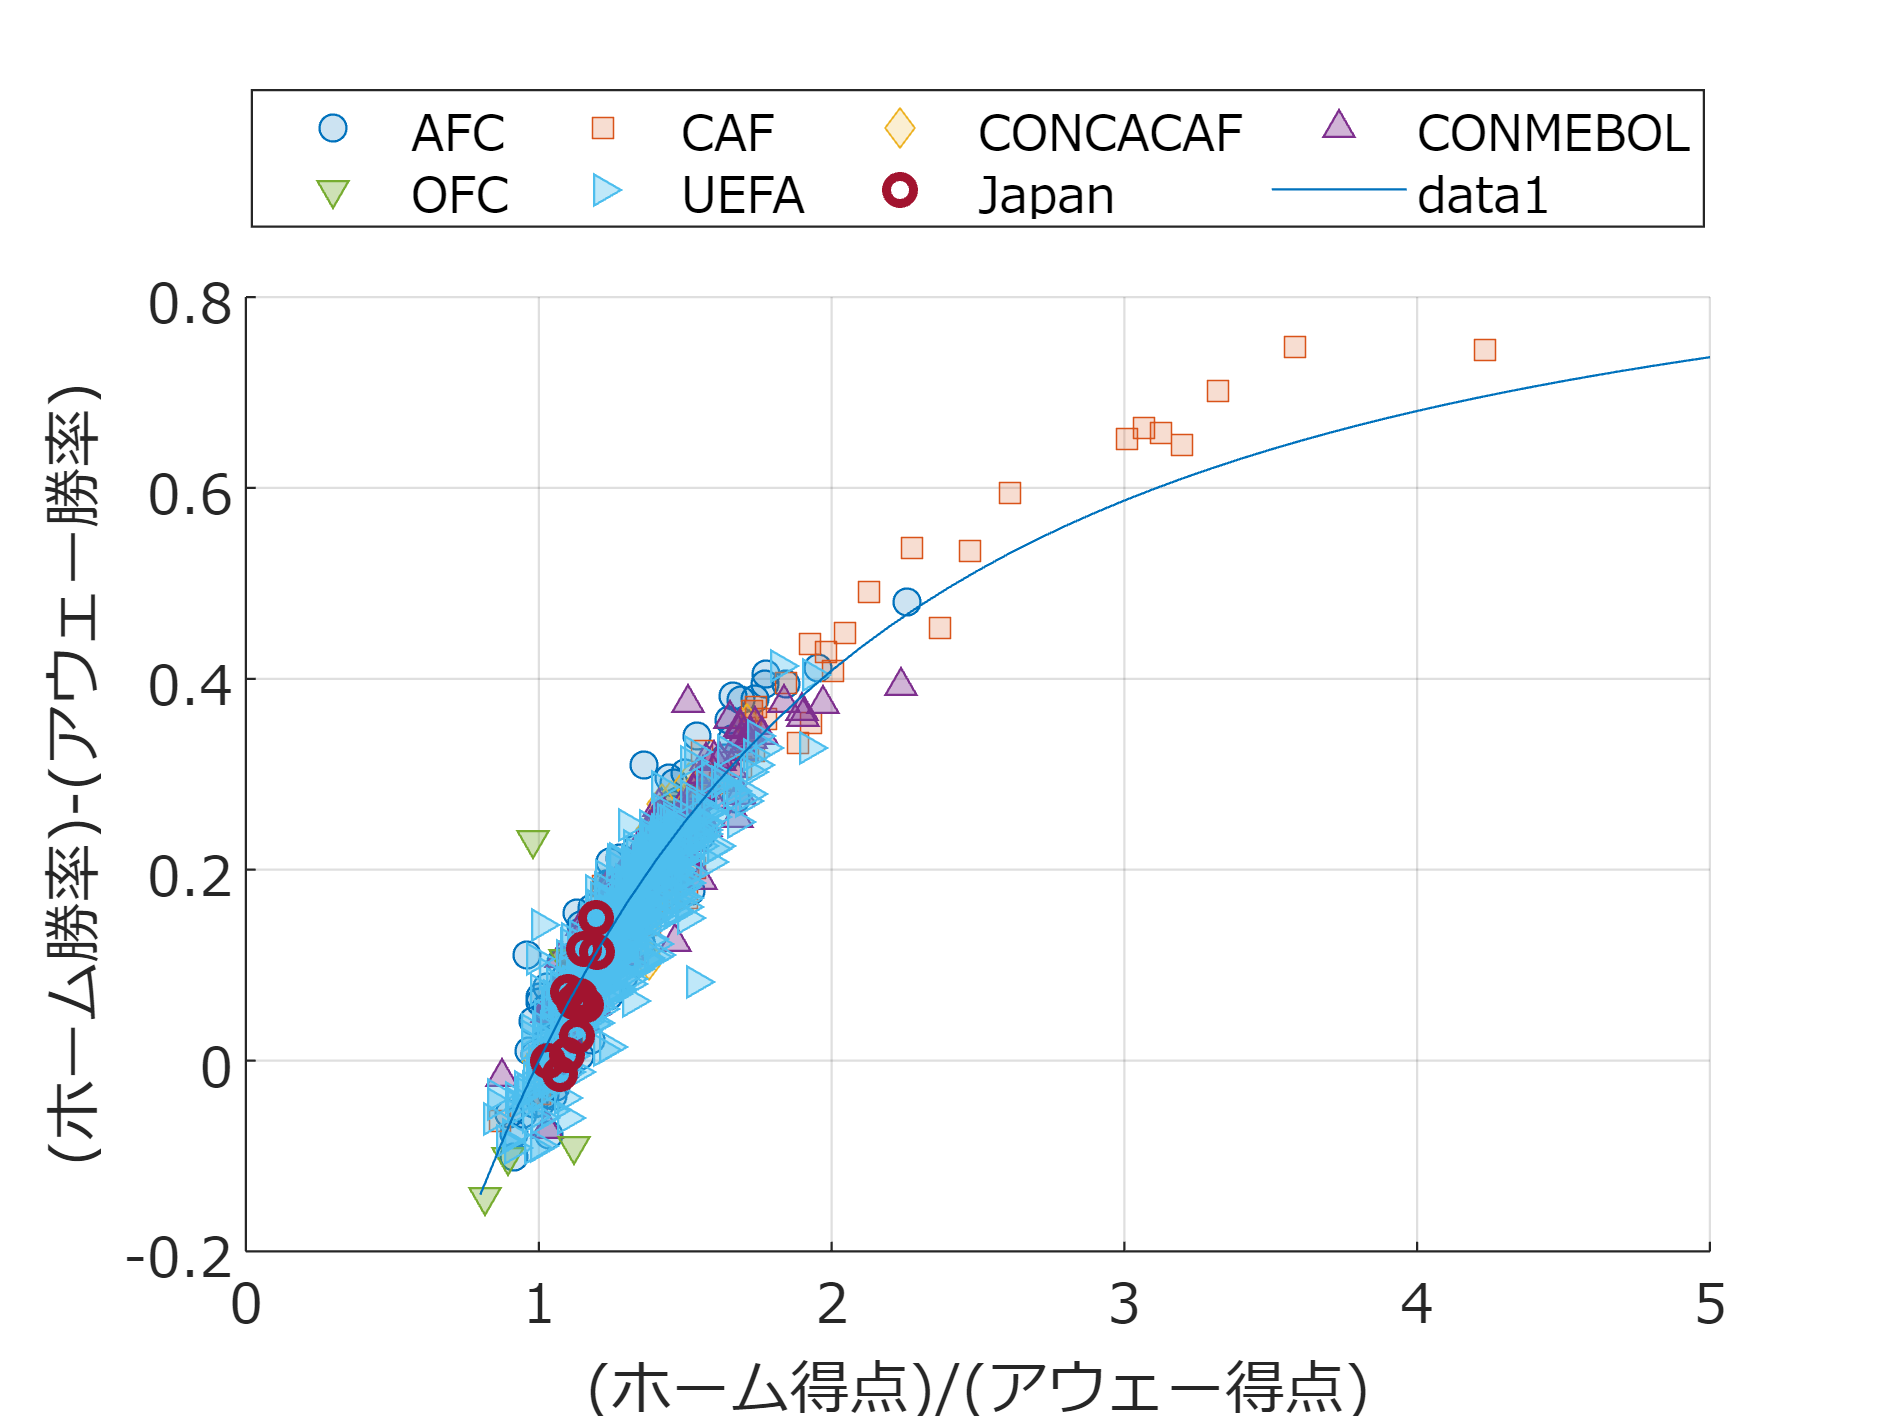

clear;
clc;
close all;

muTotalGoals=2.8;   %2チーム合計の平均得点
xVals=(0.8:0.1:5)';
yVals=[];
for xVal=xVals'  %得失点比
    muGF=muTotalGoals*xVal/(1+xVal);
    muGA=muTotalGoals*1/(1+xVal);
    pMat=predByPoisson(muGF, muGA);
    yVals=[yVals;pMat(1)-pMat(3)];
end

figure;
openfig('fig_homeAdv-WinProbDiff.fig');
hold on;
plot(xVals,yVals);
exportgraphics(gcf,'fig_Exercise_Chap0502.pdf');